## Reference Information

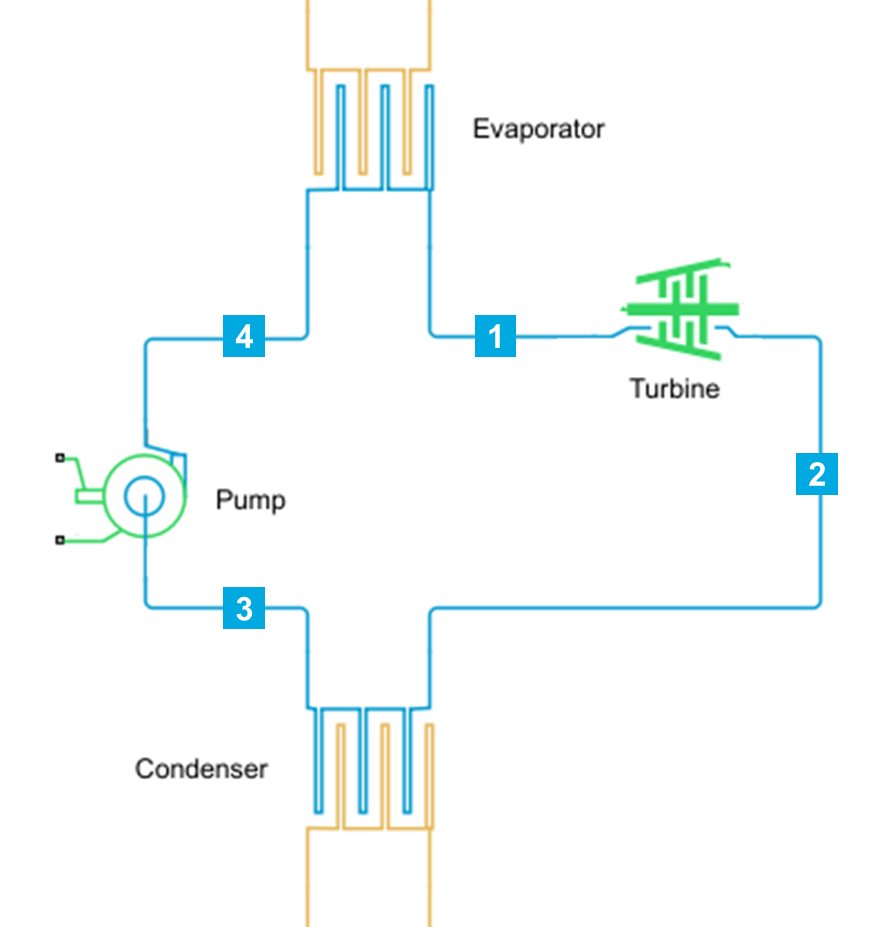  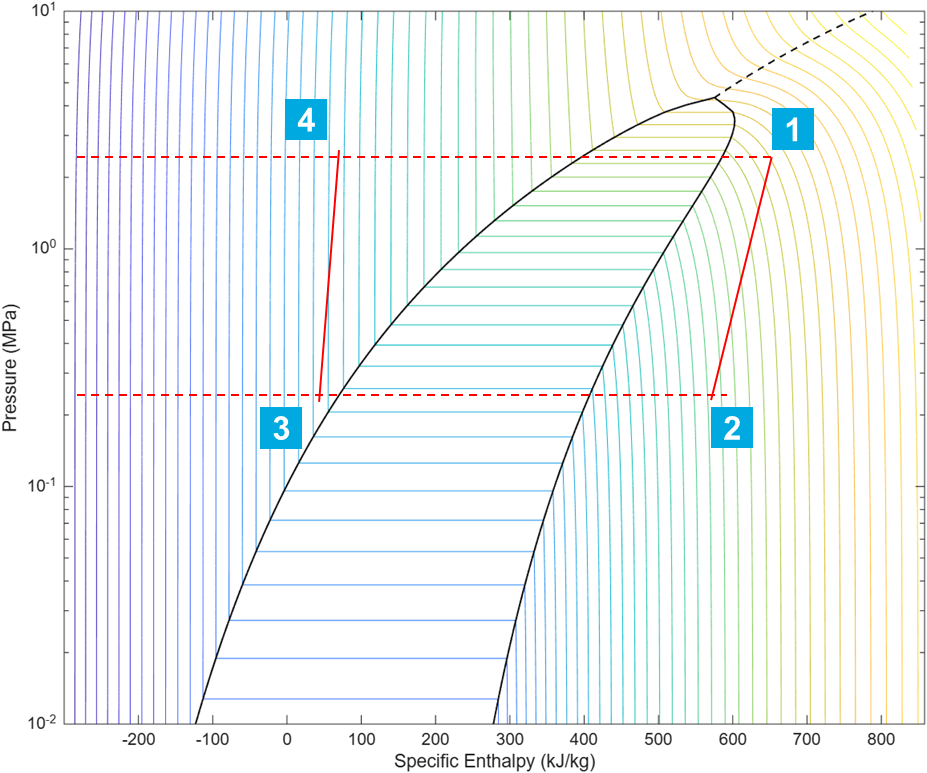

NominalStates = struct;

NominalStates.T = [300 240 132 145]; % degC
NominalStates.P = [2.3 0.23 0.23 2.3]; % MPa
NominalStates.H = [650.7 577.8 43.516 72.3]; % kJ/kg
NominalStates.mdot = 4.6;  % kg/s
NominalStates.Wout = 266.8; % kW
NominalStates.eta  = 0.1004; % 1

Evaporator = struct;
Evaporator.Oil   = struct;  % heating oil
Evaporator.Fluid = struct;  % working fluid, Toluene
Evaporator.Fluid.T = [212,273,273,300]; % In, Sat Liq, Sat Vap, Out
Evaporator.Oil.T   = [321.54,348.17,379.41,390];
Evaporator.Heat    = [737.288,906.522,317.768]; % kW
Evaporator.Oil.mdot = 9.0; % kg/s, from Sec 3.3.1(2), need to verify
Evaporator.Fluid.mdot = NominalStates.mdot;

Condenser = struct;
Condenser.Water = struct;  % cooling water
Condenser.Fluid = struct;  % working fluid, Toluene
Condenser.Fluid.T = [240,142,142,132]; % In, Sat Vap, Sat Liq, Out
Condenser.Water.T = [78.8,59.6,22.4,20];
Condenser.Heat    = [798.79,1558.67,100.52]; % kW
% Condenser.Water.mdot = nan;  % can't find info
Condenser.Fluid.mdot = NominalStates.mdot;

## Consistency Check

#### Turbine 

compare (H1-H2)*mdot & Wout.

NominalStates.mdot * (NominalStates.H(1) - NominalStates.H(2))

ans = 335.3400

NominalStates.Wout

ans = 266.8000

Looks like fluid work is higher than turbine work.  It may reflect turbine efficiency & loss.

It may also because of the steam kinetic energy loss (less likely).

#### Condenser 

compare (H2-H3)*mdot & Condenser heat.

NominalStates.mdot * (NominalStates.H(2) - NominalStates.H(3))

ans = 2.4577e+03

sum(Condenser.Heat)

ans = 2.4580e+03

VERY close.  Condenser heat data can be trusted.

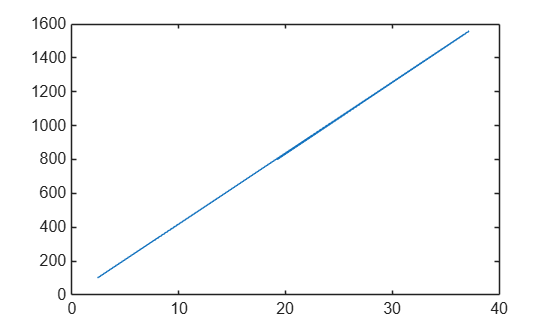

figure(1); clf;
plot(diff(-Condenser.Water.T),Condenser.Heat)
xlim([0 40]); ylim([0 1600]);

Aligns very well as a straight line across zero.  Water temperature data can be trusted.

#### Evaporator 

compare (H1-H4)*mdot & Evaporator heat.

NominalStates.mdot * (NominalStates.H(1) - NominalStates.H(4))

ans = 2.6606e+03

sum(Evaporator.Heat)

ans = 1.9616e+03

VERY different.  WHY??

Reported evaporator heat is much lower than enthalpy change in Toluene.

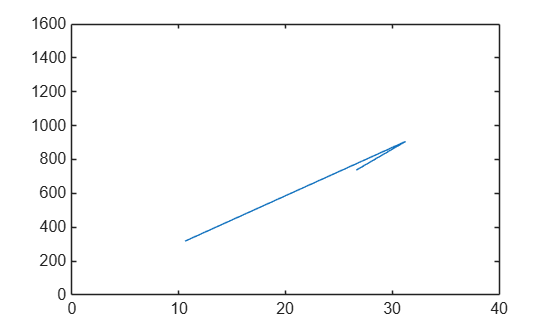

figure(2); clf;
plot(diff(Evaporator.Oil.T),Evaporator.Heat)
xlim([0 40]); ylim([0 1600]);

Nearly a straight line.  Curvature can be due to Cp as a function of temperature.  Need to verify.

## Save Data

save("parameters.mat","Evaporator","Condenser","NominalStates")